# **WM9QE: Applied Statistics for Artificial Intelligence**

**Independent Learning Exercises (Solutions): Analysis of Variance (ANOVA) **

In this section, you will practice writing MATLAB code for AI & Data Science examples using. Try to solve each problem by writing your own code below the description. Before attempting these exercises, make sure you have reviewed all sections of the MATLAB Programming seminar for ANOVA. 

## Exercise 1: Sensor Type and Signal Noise

**Scenario:** You compare signal noise levels (dB) from three types of wearable sensors: EEG, ECG, and EMG. Each was tested on 5 patients.

**Task: **Test whether **mean noise levels** differ among sensor types.

% >>> Write your code here <<<


**Answer:**

clear; clc;

%% --- Step 1. Define the data ---
EEG = [3.2 3.4 3.1 3.3 3.2];
ECG = [2.8 2.9 2.7 3.0 2.8];
EMG = [3.6 3.5 3.8 3.7 3.6];

% Combine all data and group labels
Noise = [EEG ECG EMG]';
Group = [repmat({'EEG'},5,1);
         repmat({'ECG'},5,1);
         repmat({'EMG'},5,1)];

%% --- Step 2. Descriptive statistics ---
means = [mean(EEG), mean(ECG), mean(EMG)];
stds  = [std(EEG), std(ECG), std(EMG)];
fprintf('Mean Noise Levels (dB): EEG = %.2f | ECG = %.2f | EMG = %.2f\n', means);

Mean Noise Levels (dB): EEG = 3.24 | ECG = 2.84 | EMG = 3.64


fprintf('Standard Deviations: EEG = %.2f | ECG = %.2f | EMG = %.2f\n\n', stds);

Standard Deviations:    EEG = 0.11 | ECG = 0.11 | EMG = 0.11




%% --- Step 3. Perform One-Way ANOVA ---
[p, tbl, stats] = anova1(Noise, Group, 'off'); 
disp('--- One-Way ANOVA Results ---');

--- One-Way ANOVA Results ---


disp(tbl);

    {'来源'}    {'SS'    }    {'df'}    {'MS'      }    {'F'       }    {'p 值(F)'   }
    {'组'  }    {[1.6000]}    {[ 2]}    {[  0.8000]}    {[ 61.5385]}    {[4.9159e-07]}
    {'误差'}    {[0.1560]}    {[12]}    {[  0.0130]}    {0×0 double}    {0×0 double  }
    {'合计'}    {[1.7560]}    {[14]}    {0×0 double}    {0×0 double}    {0×0 double  }




%% --- Step 4. Post-hoc comparison (Tukey HSD) ---
fprintf('\n--- Tukey HSD Multiple Comparison ---\n');


--- Tukey HSD Multiple Comparison ---


c = multcompare(stats, 'Display', 'off');
disp(array2table(c, 'VariableNames', ...
    {'Group1','Group2','Lower_CI','Mean_Diff','Upper_CI','p_Value'}));

    Group1    Group2    Lower_CI    Mean_Diff    Upper_CI     p_Value  
    ______    ______    ________    _________    ________    __________

      1         2        0.20762       0.4        0.59238    0.00034379
      1         3       -0.59238      -0.4       -0.20762    0.00034379
      2         3       -0.99238      -0.8       -0.60762    3.2239e-07



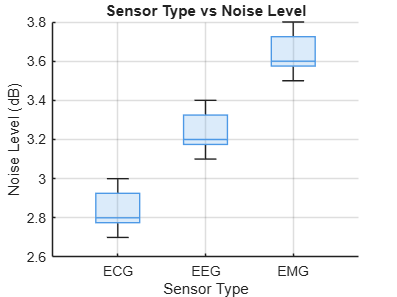


%% --- Step 5. Visualization: Box Plot with Mean Overlay ---
boxchart(categorical(Group), Noise, 'BoxFaceColor', [0.3 0.6 0.9]);
hold on;
title('Sensor Type vs Noise Level');
xlabel('Sensor Type');
ylabel('Noise Level (dB)');
grid on;
hold off;


%% --- Step 6. Interpretation ---
fprintf('\nInterpretation:\n');


Interpretation:


if p < 0.05
    fprintf(' Significant difference among sensor types (p = %.4f)\n', p);
else
    fprintf(' No significant difference among sensor types (p = %.4f)\n', p);
end

 Significant difference among sensor types (p = 0.0000)


## Exercise 2: Data Split Strategy

**Scenario: **You compared **three data split strategies** for model evaluation: **Holdout**, **K-Fold**, and **Bootstrap**. Each strategy was repeated **6** times; the **F1 score** was recorded.

**Task:**Test whether the mean F1 differs across split strategies.

% >>> Write your code here <<<

**Answer:**

clear; clc;

%% --- Step 1. Define F1 data for each split strategy ---
Holdout = [0.81 0.82 0.80 0.83 0.82 0.81];
KFold   = [0.85 0.84 0.86 0.85 0.84 0.86];
Bootstr = [0.83 0.82 0.84 0.83 0.82 0.83];

% Combine all values into a single vector
F1 = [Holdout KFold Bootstr]';

% Create group labels
Group = [repmat({'Holdout'},6,1);
         repmat({'KFold'},6,1);
         repmat({'Bootstrap'},6,1)];

%% --- Step 2. Descriptive Statistics ---
means = [mean(Holdout), mean(KFold), mean(Bootstr)];
stds  = [std(Holdout), std(KFold), std(Bootstr)];
fprintf('Mean F1 scores: Holdout = %.3f | K-Fold = %.3f | Bootstrap = %.3f\n', means);

Mean F1 scores: Holdout = 0.815 | K-Fold = 0.850 | Bootstrap = 0.828


fprintf('Standard deviations: Holdout = %.3f | K-Fold = %.3f | Bootstrap = %.3f\n\n', stds);

Standard deviations: Holdout = 0.010 | K-Fold = 0.009 | Bootstrap = 0.008




%% --- Step 3. Perform One-Way ANOVA ---
[p, tbl, stats] = anova1(F1, Group, 'off');  % suppress figure
disp('--- One-Way ANOVA Table ---');

--- One-Way ANOVA Table ---


disp(tbl);

    {'来源'}    {'SS'    }    {'df'}    {'MS'        }    {'F'       }    {'p 值(F)'   }
    {'组'  }    {[0.0037]}    {[ 2]}    {[    0.0019]}    {[ 22.7703]}    {[2.8532e-05]}
    {'误差'}    {[0.0012]}    {[15]}    {[8.2222e-05]}    {0×0 double}    {0×0 double  }
    {'合计'}    {[0.0050]}    {[17]}    {0×0 double  }    {0×0 double}    {0×0 double  }




%% --- Step 4. Post-hoc Multiple Comparisons (Tukey HSD) ---
fprintf('\n--- Tukey HSD Multiple Comparisons ---\n');


--- Tukey HSD Multiple Comparisons ---


c = multcompare(stats, 'CType', 'tukey-kramer', 'Display', 'off');
disp(array2table(c, 'VariableNames', ...
    {'Group1','Group2','Lower_CI','Mean_Diff','Upper_CI','p_Value'}));

    Group1    Group2    Lower_CI     Mean_Diff     Upper_CI      p_Value  
    ______    ______    _________    _________    __________    __________

      1         2       -0.048598       -0.035     -0.021402    2.0569e-05
      1         3       -0.026932    -0.013333    0.00026497      0.055001
      2         3       0.0080684     0.021667      0.035265     0.0023704




%% --- Step 5. Interpretation ---
fprintf('\nInterpretation:\n');


Interpretation:


if p < 0.05
    fprintf('Significant difference between data split strategies (p = %.4f)\n', p);
else
    fprintf('No significant difference between strategies (p = %.4f)\n', p);
end

Significant difference between data split strategies (p = 0.0000)


## Exercise 3: Imaging Modality × Preprocessing Method

**Scenario:**

Three imaging modalities (CT, MRI, PET) were processed using three denoising methods (Median, Gaussian, Bilateral). The **SNR (Signal-to-Noise Ratio)** of each combination was measured once.

**Task:** Test if SNR depends on **modality**, **method**, or both.

% >>> Write your code here <<<


**Answer:**

clear; clc;

%% Step 1. Define data
SNR = [35 37 38;   % CT
       42 45 46;   % MRI
       30 33 34];  % PET
rowLabels = {'CT','MRI','PET'};
colLabels = {'Median','Gaussian','Bilateral'};

disp('SNR Matrix (dB):');

SNR Matrix (dB):


disp(array2table(SNR, 'VariableNames', colLabels, 'RowNames', rowLabels));

           Median    Gaussian    Bilateral
           ______    ________    _________

    CT       35         37          38    
    MRI      42         45          46    
    PET      30         33          34    




%% Step 2. Perform Two-Way ANOVA (No replication)
[p, tbl] = anova2(SNR, 1, 'off');
disp('--- Two-Way ANOVA (No Replication) Results ---');

--- Two-Way ANOVA (No Replication) Results ---


disp(tbl);

    {'来源'}    {'SS'      }    {'df'}    {'MS'      }    {'F'       }    {'p 值(F)'   }
    {'列'  }    {[ 21.5556]}    {[ 2]}    {[ 10.7778]}    {[ 97.0000]}    {[4.0812e-04]}
    {'行'  }    {[221.5556]}    {[ 2]}    {[110.7778]}    {[997.0000]}    {[4.0080e-06]}
    {'误差'}    {[  0.4444]}    {[ 4]}    {[  0.1111]}    {0×0 double}    {0×0 double  }
    {'合计'}    {[243.5556]}    {[ 8]}    {0×0 double}    {0×0 double}    {0×0 double  }




%% Step 3. Interpret Results
p_rows = p(1);    % Imaging modality (row factor)
p_cols = p(2);    % Preprocessing method (column factor)

fprintf('\nInterpretation:\n');


Interpretation:


fprintf('p(Modality) = %.4f\n', p_rows);

p(Modality)   = 0.0004


fprintf('p(Method) = %.4f\n', p_cols);

p(Method)     = 0.0000



if p_rows < 0.05
    fprintf('Significant difference between imaging modalities.\n');
else
    fprintf('No significant difference between imaging modalities.\n');
end

Significant difference between imaging modalities.



if p_cols < 0.05
    fprintf('Significant difference between preprocessing methods.\n');
else
    fprintf('No significant difference between preprocessing methods.\n');
end

Significant difference between preprocessing methods.


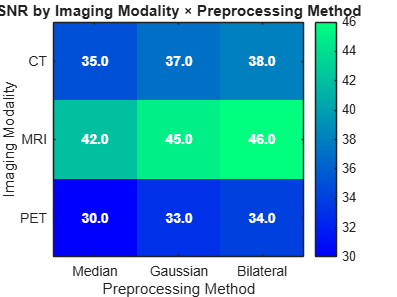


%% Step 4. Visualization
imagesc(SNR);
colormap(winter);
colorbar;
title('SNR by Imaging Modality × Preprocessing Method');
xlabel('Preprocessing Method'); ylabel('Imaging Modality');
xticks(1:3); xticklabels(colLabels);
yticks(1:3); yticklabels(rowLabels);
[X, Y] = meshgrid(1:3, 1:3);
text(X(:), Y(:), compose('%.1f', SNR(:)), ...
    'Color','w','FontSize',10,'FontWeight','bold', ...
    'HorizontalAlignment','center');

## Exercise 4: Clinical AI Models’ Latency

**Scenario: **You compared average latency (ms) for 4 AI models used in clinical data triage. Each model was evaluated 6 times.

**Task:** Determine whether latency differs significantly across models.

% >>> Write your code here <<<


**Answer:**

clear; clc;

%% Step 1. Define data
Latency = [132 134 133 135 136 132;   % Model A
            128 129 127 130 128 129;   % Model B
            142 143 140 141 142 144;   % Model C
            138 137 139 136 138 137];  % Model D

Models = {'ModelA','ModelB','ModelC','ModelD'};

% Display data table
disp('Latency (ms) for AI Models:');

Latency (ms) for AI Models:


disp(array2table(Latency, 'RowNames', Models, ...
    'VariableNames', strcat('Trial', string(1:6))));

              Trial1    Trial2    Trial3    Trial4    Trial5    Trial6
              ______    ______    ______    ______    ______    ______

    ModelA     132       134       133       135       136       132  
    ModelB     128       129       127       130       128       129  
    ModelC     142       143       140       141       142       144  
    ModelD     138       137       139       136       138       137  




%% Step 2. Prepare group labels for ANOVA
Group = [repmat({'ModelA'},6,1);
         repmat({'ModelB'},6,1);
         repmat({'ModelC'},6,1);
         repmat({'ModelD'},6,1)];

%% Step 3. Perform one-way ANOVA
[p, tbl, stats] = anova1(Latency(:), Group, 'off');
disp('--- One-Way ANOVA Results ---');

--- One-Way ANOVA Results ---


disp(tbl);

    {'来源'}    {'SS'      }    {'df'}    {'MS'      }    {'F'       }    {'p 值(F)' }
    {'组'  }    {[ 44.1667]}    {[ 3]}    {[ 14.7222]}    {[  0.5062]}    {[  0.6824]}
    {'误差'}    {[581.6667]}    {[20]}    {[ 29.0833]}    {0×0 double}    {0×0 double}
    {'合计'}    {[625.8333]}    {[23]}    {0×0 double}    {0×0 double}    {0×0 double}




%% Step 4. Interpret results
fprintf('\nInterpretation:\n');


Interpretation:


fprintf('p-value = %.4f\n', p);

p-value = 0.6824


if p < 0.05
    fprintf('Significant difference detected between AI models.\n');
else
    fprintf('No significant difference detected between AI models.\n');
end

No significant difference detected between AI models.


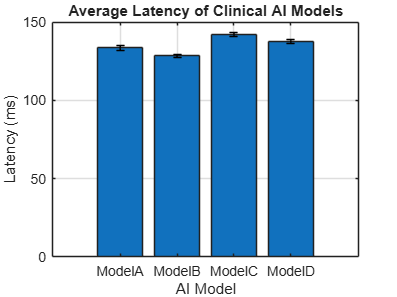


%% Step 5. Visualization
meanLatency = mean(Latency, 2);
stdLatency  = std(Latency, 0, 2);

bar(meanLatency); hold on;
errorbar(1:4, meanLatency, stdLatency, 'k', 'LineStyle', 'none', 'LineWidth', 1);
set(gca, 'XTickLabel', Models, 'FontSize', 10);
xlabel('AI Model');
ylabel('Latency (ms)');
title('Average Latency of Clinical AI Models');
grid on;
hold off;

## Exercise 5: IoT Device × Location

**Scenario: **Three IoT health-monitoring devices were deployed in three hospital rooms. The recorded **temperature stability (°C)** was averaged per room.

**Task: **Test if **device type** or **location** affects measurement stability.

% >>> Write your code here <<<


**Answer:**

clear; clc;

%% Step 1. Define data
Temp = [22.3 22.5 22.8;   % Device A
        22.1 22.3 22.5;   % Device B
        21.8 22.0 22.2];  % Device C

Devices = {'Device A','Device B','Device C'};
Locations = {'Room 1','Room 2','Room 3'};

disp('Temperature Stability (°C):');

Temperature Stability (°C):


disp(array2table(Temp, 'VariableNames', Locations, 'RowNames', Devices));

                Room 1    Room 2    Room 3
                ______    ______    ______

    Device A     22.3      22.5      22.8 
    Device B     22.1      22.3      22.5 
    Device C     21.8        22      22.2 




%% Step 2. Perform two-way ANOVA (no replication)
[p, tbl] = anova2(Temp, 1, 'off');
disp('--- Two-Way ANOVA (No Replication) Results ---');

--- Two-Way ANOVA (No Replication) Results ---


disp(tbl);

    {'来源'}    {'SS'    }    {'df'}    {'MS'      }    {'F'       }    {'p 值(F)'   }
    {'列'  }    {[0.2822]}    {[ 2]}    {[  0.1411]}    {[127.0000]}    {[2.4037e-04]}
    {'行'  }    {[0.4289]}    {[ 2]}    {[  0.2144]}    {[193.0000]}    {[1.0519e-04]}
    {'误差'}    {[0.0044]}    {[ 4]}    {[  0.0011]}    {0×0 double}    {0×0 double  }
    {'合计'}    {[0.7156]}    {[ 8]}    {0×0 double}    {0×0 double}    {0×0 double  }




%% Step 3. Interpret results
p_device = p(1);   % Row factor
p_location = p(2); % Column factor

fprintf('\nInterpretation:\n');


Interpretation:


fprintf('p(Device) = %.4f\n', p_device);

p(Device)   = 0.0002


fprintf('p(Location) = %.4f\n', p_location);

p(Location) = 0.0001



if p_device < 0.05
    fprintf('Significant difference detected between IoT devices.\n');
else
    fprintf('No significant difference between IoT devices.\n');
end

Significant difference detected between IoT devices.



if p_location < 0.05
    fprintf('Significant difference detected between locations.\n');
else
    fprintf('No significant difference between locations.\n');
end

Significant difference detected between locations.


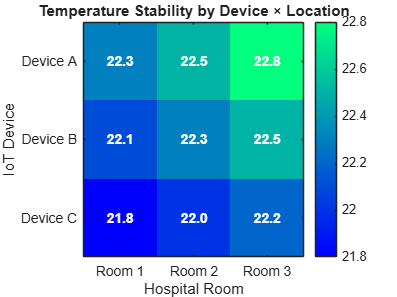


%% Step 4. Visualization
imagesc(Temp);
colormap(winter);
colorbar;
title('Temperature Stability by Device × Location');
xlabel('Hospital Room'); ylabel('IoT Device');
xticks(1:3); xticklabels(Locations);
yticks(1:3); yticklabels(Devices);

% Add text labels for values
[X, Y] = meshgrid(1:3, 1:3);
text(X(:), Y(:), compose('%.1f', Temp(:)), ...
    'Color','w','FontSize',10,'FontWeight','bold', ...
    'HorizontalAlignment','center');

## Exercise 6: Augmentation × Normalization

**Scenario: **Images were preprocessed using **three augmentation policies** (Light, Medium, Heavy)

and **three normalization schemes** (MinMax, ZScore, Robust). For each combination, classification **accuracy (%)** was measured **once**.

**Task: **Use **two-way ANOVA (without replication)** to test main effects and interaction.

% >>> Write your code here <<<

**Answer:**

clear; clc;

%% Step 1. Define Accuracy data matrix
% Rows: Training Algorithms (A1, A2, A3)
% Columns: Dataset Types (D1, D2, D3)
Acc = [86 88 87;   % Algorithm 1
       88 90 89;   % Algorithm 2
       85 87 86];  % Algorithm 3

Algorithms = {'Alg-1','Alg-2','Alg-3'};
Datasets = {'Dataset-A','Dataset-B','Dataset-C'};

disp('Accuracy Matrix (%):');

Accuracy Matrix (%):


disp(array2table(Acc, 'VariableNames', Datasets, 'RowNames', Algorithms));

             Dataset-A    Dataset-B    Dataset-C
             _________    _________    _________

    Alg-1       86           88           87    
    Alg-2       88           90           89    
    Alg-3       85           87           86    




%% Step 2. Two-way ANOVA (without replication)
[p, tbl] = anova2(Acc, 1, 'off');
disp('--- Two-Way ANOVA (No Replication) Results ---');

--- Two-Way ANOVA (No Replication) Results ---


disp(tbl);

    {'来源'}    {'SS'        }    {'df'}    {'MS'        }    {'F'         }    {'p 值(F)'   }
    {'列'  }    {[         6]}    {[ 2]}    {[         3]}    {[6.7554e+15]}    {[8.7651e-32]}
    {'行'  }    {[   14.0000]}    {[ 2]}    {[    7.0000]}    {[1.5763e+16]}    {[1.6099e-32]}
    {'误差'}    {[1.7764e-15]}    {[ 4]}    {[4.4409e-16]}    {0×0 double  }    {0×0 double  }
    {'合计'}    {[        20]}    {[ 8]}    {0×0 double  }    {0×0 double  }    {0×0 double  }




%% Step 3. Extract and interpret p-values
p_alg = p(1);    % Row factor = Algorithm
p_data = p(2);   % Column factor = Dataset

fprintf('\nInterpretation:\n');


Interpretation:


fprintf('p(Algorithm) = %.4f\n', p_alg);

p(Algorithm) = 0.0000


fprintf('p(Dataset)   = %.4f\n', p_data);

p(Dataset)   = 0.0000



if p_alg < 0.05
    fprintf('Significant difference between training algorithms.\n');
else
    fprintf('No significant difference between training algorithms.\n');
end

Significant difference between training algorithms.



if p_data < 0.05
    fprintf('Significant difference between dataset types.\n');
else
    fprintf('No significant difference between dataset types.\n');
end

Significant difference between dataset types.


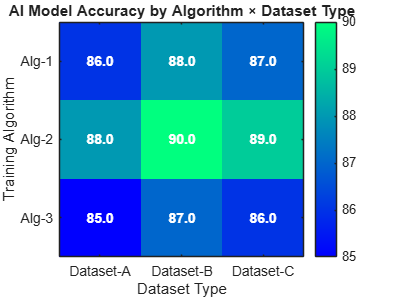


%% Step 4. Visualization
imagesc(Acc);
colormap(winter); 
colorbar;
title('AI Model Accuracy by Algorithm × Dataset Type');
xlabel('Dataset Type'); ylabel('Training Algorithm');
xticks(1:3); xticklabels(Datasets);
yticks(1:3); yticklabels(Algorithms);

% Annotate each cell with numeric values
[X, Y] = meshgrid(1:3, 1:3);
text(X(:), Y(:), compose('%.1f', Acc(:)), ...
    'Color','w','FontSize',10,'FontWeight','bold', ...
    'HorizontalAlignment','center');

## Exercise 7: Edge Device × Power Mode with Replications 

**Scenario: **You deployed a detector on **three edge devices** (Nano, Xavier, Orin) under **two power modes** (Eco, Performance). Each combination was run **4** times; **throughput (FPS)** was recorded.

**Task: **Use **two-way ANOVA with replication** to test Device, Mode, and their interaction.

% >>> Write your code here <<<


**Answer:**

clear; clc;

%% Step 1. Define data
% 3 Devices × 2 Modes × 4 Replicates
FPS(:,:,1) = [18 22; 32 45; 58 85];  % Rep 1
FPS(:,:,2) = [19 23; 31 46; 57 86];  % Rep 2
FPS(:,:,3) = [18 22; 33 44; 59 84];  % Rep 3
FPS(:,:,4) = [19 23; 32 45; 58 85];  % Rep 4

Devices = {'Device A','Device B','Device C'};
Modes = {'Standard','HighPerf'};

%% Step 2. Verify dimensions
disp('Data cube dimensions (Devices × Modes × Reps):');

Data cube dimensions (Devices × Modes × Reps):


disp(size(FPS));

     3     2     4




%% Step 3. Reshape data for anova2
% Resulting Y: (3×4=12 rows) × 2 columns
Y = reshape(permute(FPS, [1 3 2]), [], 2);

%% Step 4. Perform Two-Way ANOVA with replication
[p, tbl, stats] = anova2(Y, 4, 'off');  % 4 replicates per cell
disp('--- Two-Way ANOVA (With Replication) Results ---');

--- Two-Way ANOVA (With Replication) Results ---


disp(tbl);

    {'来源'   }    {'SS'        }    {'df'}    {'MS'        }    {'F'       }    {'p 值(F)' }
    {'列'     }    {[1.2907e+03]}    {[ 1]}    {[1.2907e+03]}    {[  2.2046]}    {[  0.1549]}
    {'行'     }    {[  685.7500]}    {[ 2]}    {[  342.8750]}    {[  0.5857]}    {[  0.5670]}
    {'交互效应'}    {[   27.5833]}    {[ 2]}    {[   13.7917]}    {[  0.0236]}    {[  0.9767]}
    {'误差'   }    {[     10538]}    {[18]}    {[  585.4444]}    {0×0 double}    {0×0 double}
    {'合计'   }    {[     12542]}    {[23]}    {0×0 double  }    {0×0 double}    {0×0 double}




%% Step 5. Interpret results
fprintf('\nInterpretation:\n');


Interpretation:


fprintf('p(Device) = %.4f\n', p(1));

p(Device)      = 0.1549


fprintf('p(Mode) = %.4f\n', p(2));

p(Mode)        = 0.5670


fprintf('p(Interaction) = %.4f\n', p(3));

p(Interaction) = 0.9767



if p(1) < 0.05
    fprintf('Significant difference between devices.\n');
else
    fprintf('No significant difference between devices.\n');
end

No significant difference between devices.


if p(2) < 0.05
    fprintf('Significant difference between operation modes.\n');
else
    fprintf('No significant difference between operation modes.\n');
end

No significant difference between operation modes.


if p(3) < 0.05
    fprintf('Significant interaction effect detected (Device × Mode).\n');
else
    fprintf('No significant interaction effect detected.\n');
end

No significant interaction effect detected.


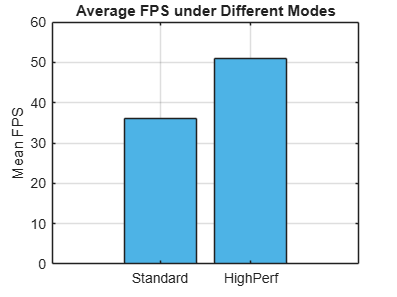


%% Step 6. Visualization
meanFPS = mean(Y);

bar(meanFPS, 'FaceColor',[0.3 0.7 0.9]);
title('Average FPS under Different Modes');
xticklabels(Modes);
ylabel('Mean FPS');
grid on;

## Exercise 8: Compression Level (One-Way ANOVA + Tukey Post-hoc)

**Scenario: **You compressed medical images using **four JPEG quality levels** (Q90, Q80, Q70, Q60).

For each level, **PSNR (dB)** was measured on **5 images**.

**Task: **Run **one-way ANOVA** and then a **Tukey HSD post-hoc test** to see which quality levels differ.

% >>> Write your code here <<<


**Answer:**

clear; clc;

%% Step 1. Define PSNR data (dB)
Q90 = [42.1 41.8 42.3 41.9 42.0];
Q80 = [39.6 39.9 39.4 39.7 39.8];
Q70 = [36.1 36.4 36.0 36.2 36.3];
Q60 = [33.0 33.2 33.1 32.9 33.0];

Quality = {'Q90','Q80','Q70','Q60'};

PSNR  = [Q90 Q80 Q70 Q60]';
Group = [repmat({'Q90'},5,1);
         repmat({'Q80'},5,1);
         repmat({'Q70'},5,1);
         repmat({'Q60'},5,1)];

disp('PSNR (dB) Measurements by Compression Quality:');

PSNR (dB) Measurements by Compression Quality:


disp(array2table([Q90' Q80' Q70' Q60'], 'VariableNames', Quality));

    Q90     Q80     Q70     Q60 
    ____    ____    ____    ____

    42.1    39.6    36.1      33
    41.8    39.9    36.4    33.2
    42.3    39.4      36    33.1
    41.9    39.7    36.2    32.9
      42    39.8    36.3      33




%% Step 2. Perform one-way ANOVA
[p, tbl, stats] = anova1(PSNR, Group, 'off');  % 'off' disables GUI
disp('--- One-Way ANOVA Results ---');

--- One-Way ANOVA Results ---


disp(tbl);

    {'来源'}    {'SS'      }    {'df'}    {'MS'      }    {'F'         }    {'p 值(F)'   }
    {'组'  }    {[232.7175]}    {[ 3]}    {[ 77.5725]}    {[2.7704e+03]}    {[6.1956e-22]}
    {'误差'}    {[  0.4480]}    {[16]}    {[  0.0280]}    {0×0 double  }    {0×0 double  }
    {'合计'}    {[233.1655]}    {[19]}    {0×0 double}    {0×0 double  }    {0×0 double  }




%% Step 3. Interpret results
fprintf('\nInterpretation:\n');


Interpretation:


fprintf('p-value = %.6f\n', p);

p-value = 0.000000


if p < 0.05
    fprintf('Significant difference in PSNR across compression levels.\n');
else
    fprintf('No significant difference between compression levels.\n');
end

Significant difference in PSNR across compression levels.



%% Step 4. Post-hoc Multiple Comparison (Tukey HSD)
[c, m, h, gnames] = multcompare(stats, 'CType','tukey-kramer', 'Display','off');

% Convert to readable table
posthocTable = array2table(c, ...
    'VariableNames', {'Group1','Group2','Lower_CI','Mean_Diff','Upper_CI','pValue'});
posthocTable.Group1 = gnames(posthocTable.Group1);
posthocTable.Group2 = gnames(posthocTable.Group2);

disp('--- Tukey HSD Post-hoc Results ---');

--- Tukey HSD Post-hoc Results ---


disp(posthocTable);

    Group1     Group2     Lower_CI    Mean_Diff    Upper_CI      pValue  
    _______    _______    ________    _________    ________    __________

    {'Q90'}    {'Q80'}     2.0372       2.34        2.6428      5.107e-13
    {'Q90'}    {'Q70'}     5.5172       5.82        6.1228              0
    {'Q90'}    {'Q60'}     8.6772       8.98        9.2828              0
    {'Q80'}    {'Q70'}     3.1772       3.48        3.7828     7.8241e-18
    {'Q80'}    {'Q60'}     6.3372       6.64        6.9428              0
    {'Q70'}    {'Q60'}     2.8572       3.16        3.4628     2.3607e-16



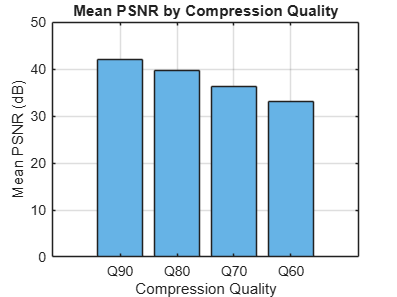


%% Step 5. Visualization
% Mean PSNR bar plot
meanVals = m(:,1);
stdVals = m(:,2);

bar(meanVals, 'FaceColor',[0.4 0.7 0.9]); hold on;
set(gca, 'XTickLabel', Quality, 'FontSize',10);
xlabel('Compression Quality');
ylabel('Mean PSNR (dB)');
title('Mean PSNR by Compression Quality');
grid on;
hold off;

## Exercise 9: Sensor Placement × Environment × Replications

**Scenario: **You evaluated **three wearable sensor placements** (Wrist, Chest, Ankle)

in **two environments** (Indoor, Outdoor). Each condition was tested **4 times**, and the **average heart-rate detection accuracy (%)** was recorded.

**Task:**Perform a **two-way ANOVA with replication** and report the effects of placement, environment, and their interaction.

% >>> Write your code here <<<


**Answer:**

clear; clc;

%% Step 1. Define data
% 3 placements × 2 environments × 4 reps
Acc(:,:,1) = [95 92; 97 94; 93 89];  % Rep 1
Acc(:,:,2) = [94 91; 96 93; 92 88];  % Rep 2
Acc(:,:,3) = [95 92; 97 95; 93 89];  % Rep 3
Acc(:,:,4) = [94 91; 96 93; 92 88];  % Rep 4

Placements = {'Front','Side','Rear'};
Environments = {'Indoor','Outdoor'};

disp('Data Cube Size (Placement × Environment × Rep):');

Data Cube Size (Placement × Environment × Rep):


disp(size(Acc));

     3     2     4




%% Step 2. Reshape for ANOVA
% Rows = placements × reps = 3×4 = 12
% Columns = environments (2)
Y = reshape(permute(Acc, [1 3 2]), [], 2);

%% Step 3. Perform Two-Way ANOVA with Replication
[p, tbl, stats] = anova2(Y, 4, 'off');
disp('--- Two-Way ANOVA (With Replication) Results ---');

--- Two-Way ANOVA (With Replication) Results ---


disp(tbl);

    {'来源'   }    {'SS'      }    {'df'}    {'MS'      }    {'F'       }    {'p 值(F)' }
    {'列'     }    {[ 63.3750]}    {[ 1]}    {[ 63.3750]}    {[ 13.3812]}    {[  0.0018]}
    {'行'     }    {[  9.7500]}    {[ 2]}    {[  4.8750]}    {[  1.0293]}    {[  0.3773]}
    {'交互效应'}    {[  0.2500]}    {[ 2]}    {[  0.1250]}    {[  0.0264]}    {[  0.9740]}
    {'误差'   }    {[ 85.2500]}    {[18]}    {[  4.7361]}    {0×0 double}    {0×0 double}
    {'合计'   }    {[158.6250]}    {[23]}    {0×0 double}    {0×0 double}    {0×0 double}




%% Step 4. Interpret results
fprintf('\nInterpretation:\n');


Interpretation:


fprintf('p(Placement) = %.4f\n', p(1));

p(Placement)   = 0.0018


fprintf('p(Environment) = %.4f\n', p(2));

p(Environment) = 0.3773


fprintf('p(Interaction) = %.4f\n', p(3));

p(Interaction) = 0.9740



if p(1) < 0.05
    fprintf('Significant difference among placements.\n');
else
    fprintf('No significant difference among placements.\n');
end

Significant difference among placements.


if p(2) < 0.05
    fprintf('Significant difference between environments.\n');
else
    fprintf('No significant difference between environments.\n');
end

No significant difference between environments.


if p(3) < 0.05
    fprintf('Significant interaction between placement and environment.\n');
else
    fprintf('No significant interaction effect detected.\n');
end

No significant interaction effect detected.


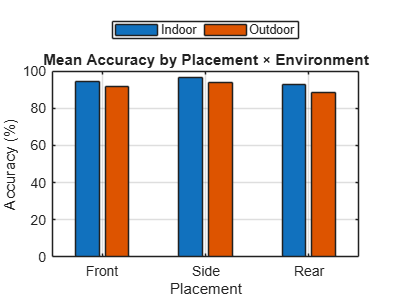


%% Step 5. Visualization
meanAcc = squeeze(mean(Acc,3));  % Average over 4 reps

bar(meanAcc);
title('Mean Accuracy by Placement × Environment');
xlabel('Placement');
ylabel('Accuracy (%)');
legend(Environments,'Location','northoutside','Orientation','horizontal');
set(gca, 'XTickLabel', Placements, 'FontSize',10);
grid on;